clc, clear, close all

path = "RBE550_assignment_transmission_SCAD_files.tar\RBE550_assignment_transmission_SCAD_files";

Import Models

% mainshaft_pde = createpde(1);
% Importing the geometry from .stl 
% mainshaft_stl = importGeometry(mainshaft_pde,"apart_transmission.stl");


Generate Meshes

% femodel = generateMesh(model);
% 
% transmission = collisionMesh(transpose(femodel.Nodes));

% box = collisionBox(50, 50, 50);

% save transmission_variables.mat transmission femodel

load transmission_variables.mat

% checkCollision(transmission, box)

% if checkCollision(transmission, box) 
%     pdeplot3D(femodel)
%      show(transmission)
%      show(box)
% end



Generate Mainshaft as Rigid Body

% create new rigid body tree with row data format structure
dhparams = [0   	pi/2	0   	0;
            0.4318	0       0       0
            0.0203	-pi/2	0.15005	0;
            0   	pi/2	0.4318	0;
            0       -pi/2	0   	0;
            0       0       0       0];


mainshaft = rigidBodyTree;
mainshaft.DataFormat = 'row';

% create 3 bodies for translation X, Y and Z
body_x = rigidBody('body_x');
body_y = rigidBody('body_y');
body_z = rigidBody('body_z');

% create 3 bodies for rotation A, B, C
body_a = rigidBody('body_a');
body_b = rigidBody('body_b');
body_c = rigidBody('body_c');

% create 3 prismatic joints for translation X, Y and Z
trans_x = rigidBodyJoint('trans_x','prismatic');
trans_y = rigidBodyJoint('trans_y','prismatic');
trans_z = rigidBodyJoint('trans_z','prismatic');

% create 3 revolute joints for rotation A, B, C
rot_a = rigidBodyJoint('rot_a','revolute');
rot_b = rigidBodyJoint('rot_b','revolute');
rot_c = rigidBodyJoint('rot_c','revolute');

% define translation direction X, Y, Z
% trans_x.JointAxis = [1 0 0];
% trans_y.JointAxis = [0 1 0];
% trans_z.JointAxis = [0 0 1];

% define rotation direction A, B, C
% rot_a.JointAxis = [1 0 0];
% rot_b.JointAxis = [0 1 0];
% rot_c.JointAxis = [0 0 1];

% setFixedTransform(trans_x,dhparams(1,:),"dh");
% setFixedTransform(trans_y,dhparams(2,:),"dh");
% setFixedTransform(trans_z,dhparams(3,:),"dh");
% setFixedTransform(rot_a,dhparams(4,:),"dh");
% setFixedTransform(rot_b,dhparams(5,:),"dh");
% setFixedTransform(rot_c,dhparams(6,:),"dh");


% connect joints to refering bodies
body_x.Joint = trans_x;
body_y.Joint = trans_y;
body_z.Joint = trans_z;
body_a.Joint = rot_a;
body_b.Joint = rot_b;
body_c.Joint = rot_c;




% Setting Transformation Matrix


% 
% setFixedTransform(trans_x,[0,0,0,0],"dh");
% setFixedTransform(trans_y,[0,0,5,0],"dh");
% setFixedTransform(trans_z,[0,0,5,0],"dh");
% setFixedTransform(rot_a,[0,0,5,0],"dh");
% setFixedTransform(rot_b,[0,0,5,0],"dh");
% setFixedTransform(rot_c,[0,0,5,0],"dh");

% add visual stl to the last rigid body in the rigid body tree structure
% addVisual(body_c,"Mesh",'apart_transmission.stl');

% connect bodies to rigid 
addBody(mainshaft,body_x,'base');
addBody(mainshaft,body_y,'body_x');
addBody(mainshaft, body_z,'body_y');
addBody(mainshaft,body_a,'body_z');
addBody(mainshaft,body_b,'body_a');
addBody(mainshaft, body_c,'body_b');


%% visualize extruder in defined position and orientation

% show(mainshaft,[0 0 0 0 0 0],'visuals','on','frames','off');
% showdetails(mainshaft)
% view(0,0)
% camproj('orthographic');


Add Collision Geometry to Mainshaft Rigid Body

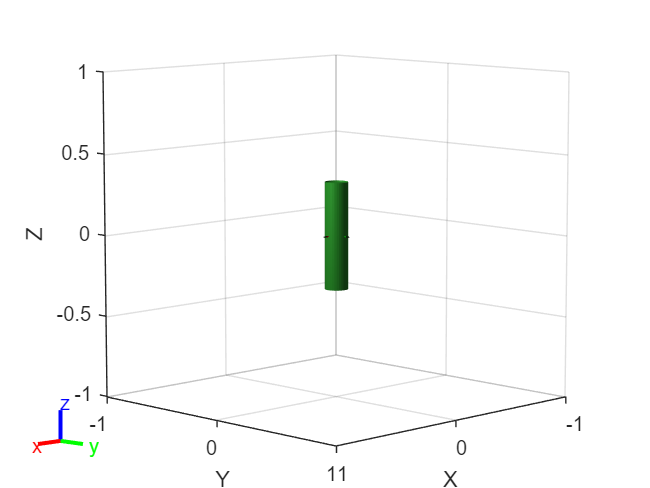

collisionObj = collisionCylinder(0.072,0.66);

addCollision(mainshaft.Bodies{end}, transmission)
addCollision(mainshaft.Bodies{end}, collisionObj)


% 
% for i = 1:mainshaft.NumBodies
%     if i > 6 && i < 10
%         % Skip these bodies.
%     else
%         addCollision(mainshaft.Bodies{i},transmission)
%     end
% end

show(mainshaft,'Collisions','on','Visuals','off');

Test

% dhparams = [0   	pi/2	0   	0;
%             0.4318	0       0       0
%             0.0203	-pi/2	0.15005	0;
%             0   	pi/2	0.4318	0;
%             0       -pi/2	0   	0;
%             0       0       0       0];
% 
% robot = rigidBodyTree;
% 
% body1 = rigidBody('body1');
% jnt1 = rigidBodyJoint('jnt1','revolute');
% 
% setFixedTransform(jnt1,dhparams(1,:),'dh');
% body1.Joint = jnt1;
% 
% addBody(robot,body1,'base')
% 
% body2 = rigidBody('body2');
% jnt2 = rigidBodyJoint('jnt2','revolute');
% body3 = rigidBody('body3');
% jnt3 = rigidBodyJoint('jnt3','revolute');
% body4 = rigidBody('body4');
% jnt4 = rigidBodyJoint('jnt4','revolute');
% body5 = rigidBody('body5');
% jnt5 = rigidBodyJoint('jnt5','revolute');
% body6 = rigidBody('body6');
% jnt6 = rigidBodyJoint('jnt6','revolute');
% 
% setFixedTransform(jnt2,dhparams(2,:),'dh');
% setFixedTransform(jnt3,dhparams(3,:),'dh');
% setFixedTransform(jnt4,dhparams(4,:),'dh');
% setFixedTransform(jnt5,dhparams(5,:),'dh');
% setFixedTransform(jnt6,dhparams(6,:),'dh');
% 
% body2.Joint = jnt2;
% body3.Joint = jnt3;
% body4.Joint = jnt4;
% body5.Joint = jnt5;
% body6.Joint = jnt6;
% 
% addBody(robot,body2,'body1')
% addBody(robot,body3,'body2')
% addBody(robot,body4,'body3')
% addBody(robot,body5,'body4')
% addBody(robot,body6,'body5')
% 
% show(robot)